# ASEN 3128 Homework 4

#### Ryan Hughes, Ponder Stine, William Watkins

## Problem 2

## Problem 2.a

### Set up the Workspace

close all;
clear all;
clc;

### Declare Constants

global g I_x I_y I_z m R G_body g_body fb L_BE L_EB

g = 9.81; % [m/s^2], acceleration of gravity
m = 0.068; % [kg], mass of the quadcopter
R = 0.060; % [m], distance from CG to motors
I_x = 5.8 * 10 ^ (-5); % [kg*m^2], moment of inertia about x-axis
I_y = 7.2 * 10 ^ (-5); % [kg*m^2], moment of inertia about y-axis
I_z = 1.0 * 10 ^ (-4); % [kg*m^2], moment of inertia about z-axis
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
p = 0;
q = 0;
r = 0;
phi = deg2rad(5);
theta = 0;
psi = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];
tSpan = 0:0.01:10;

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationLin', tSpan, initialState);

### Plotting the results

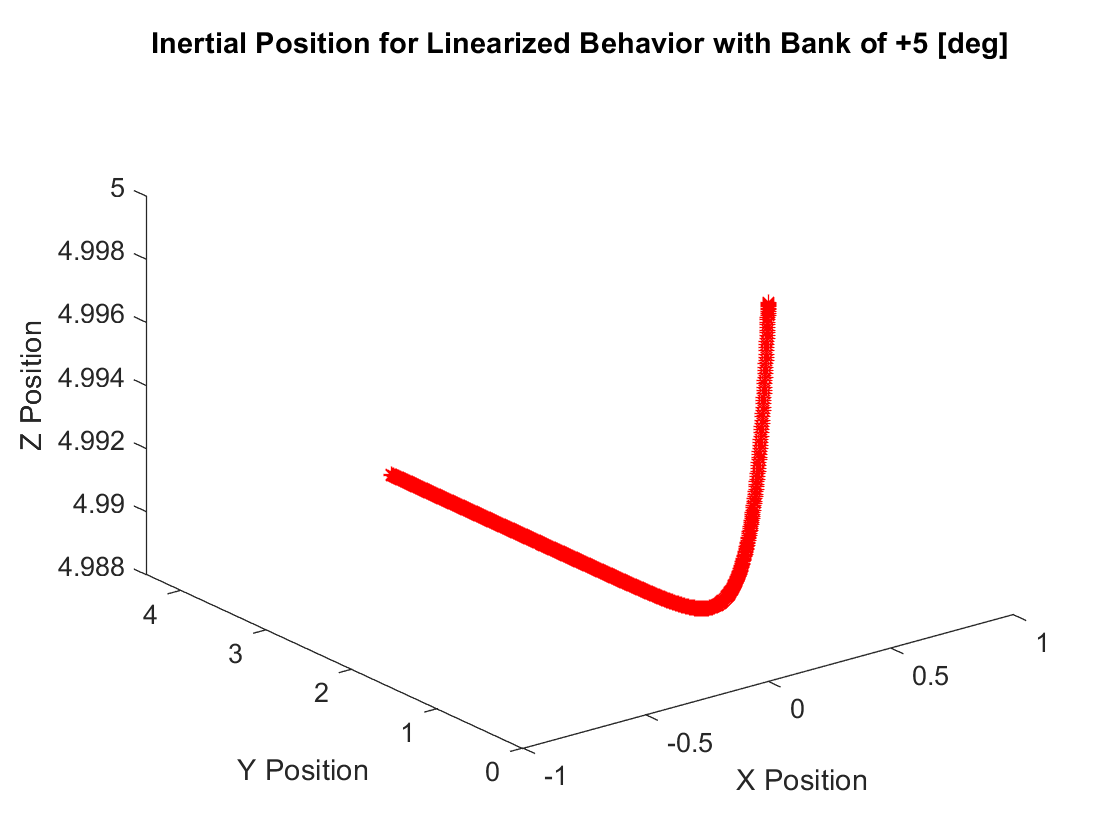

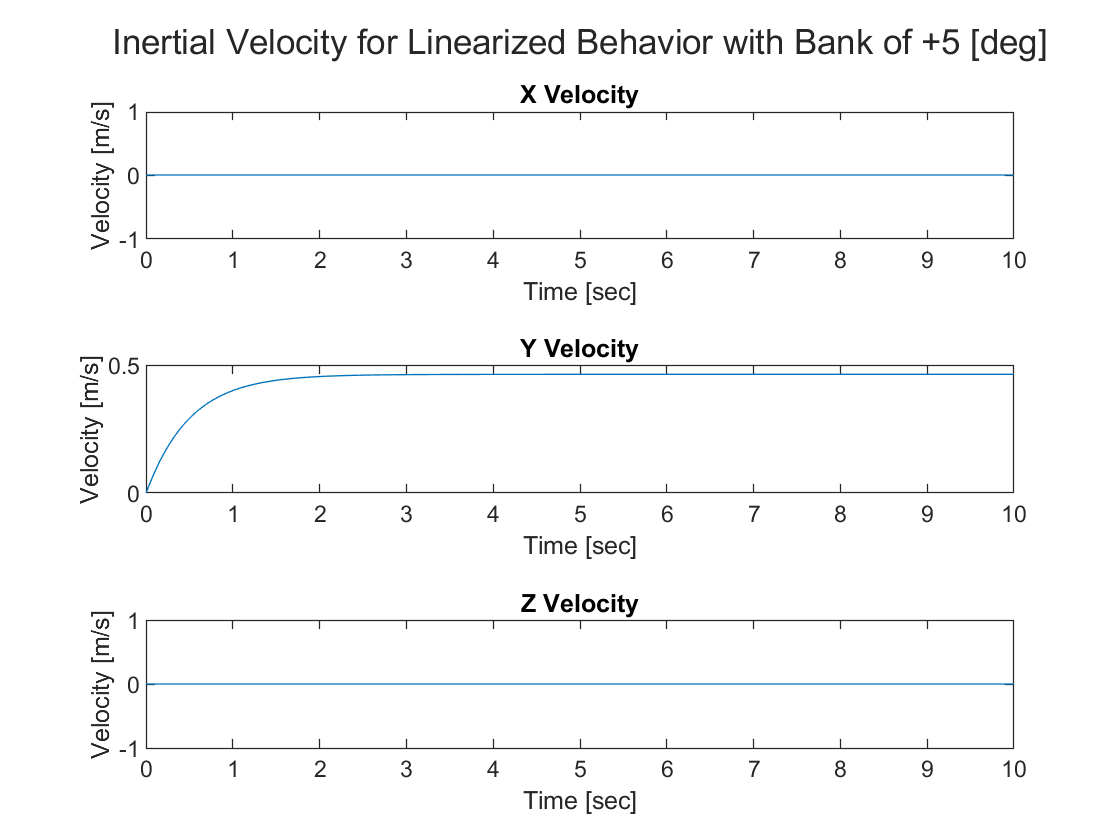

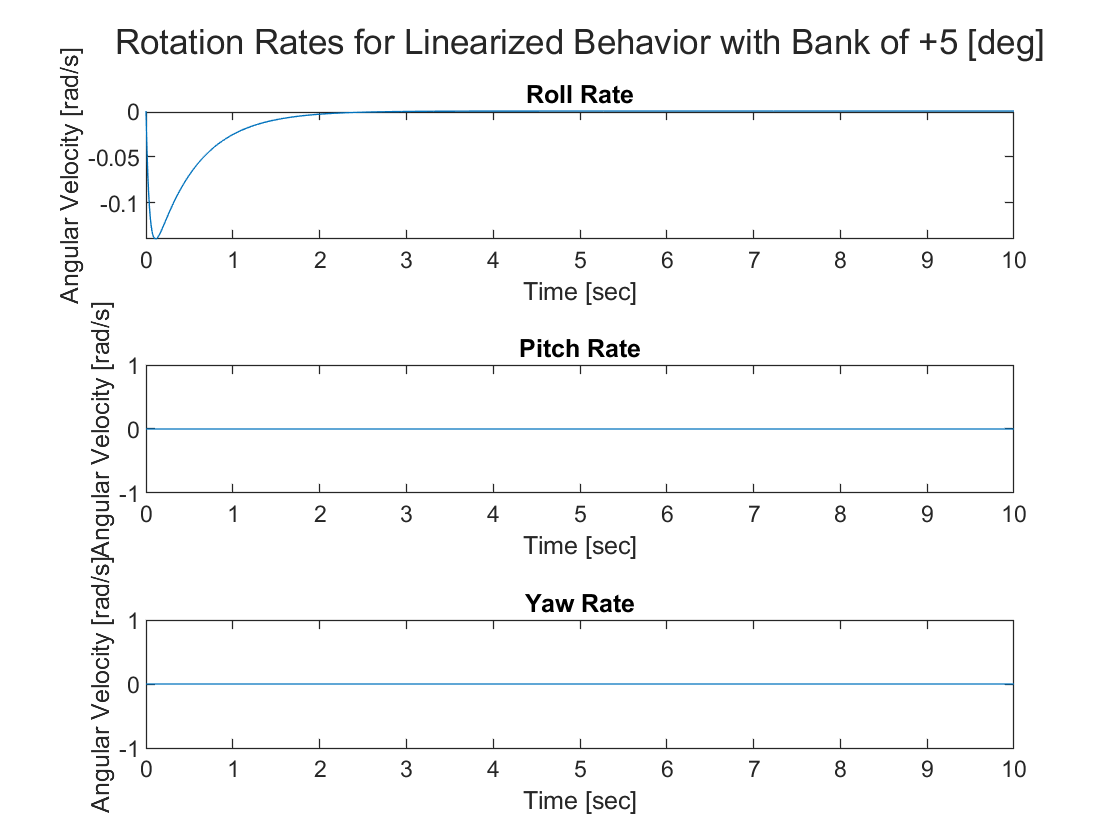

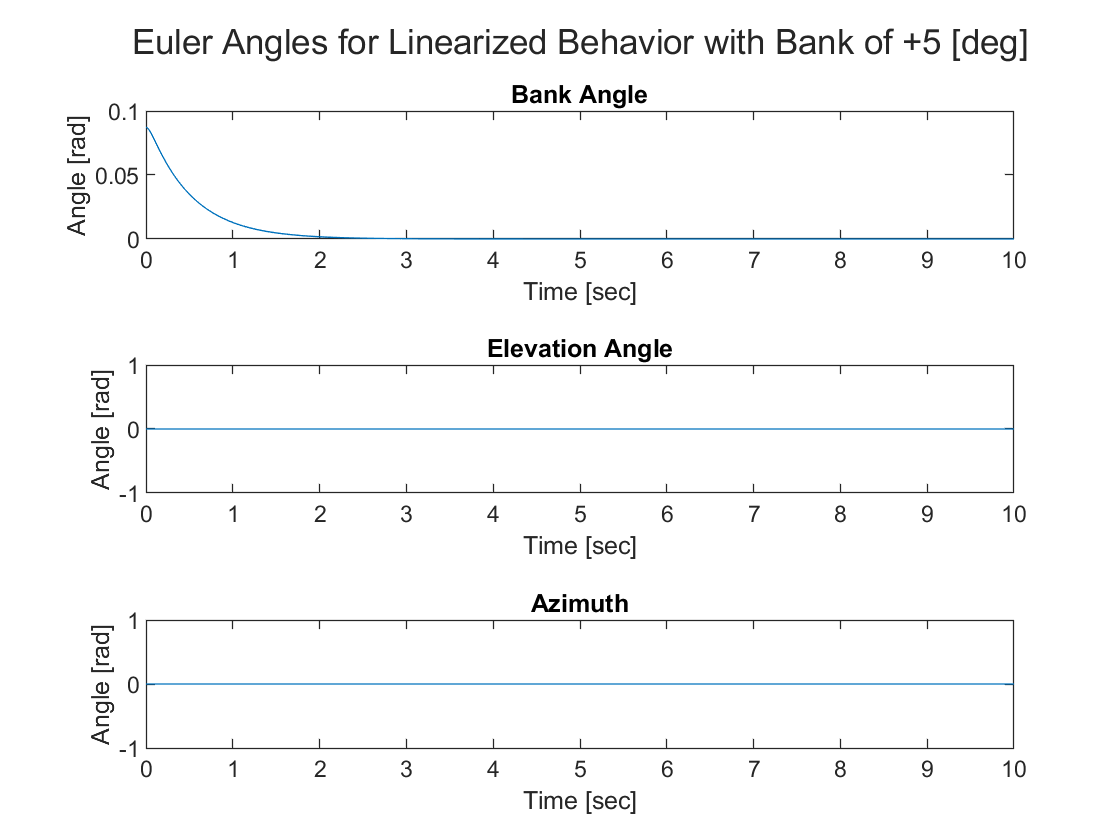

plutter(t,y,'Linearized Behavior with Bank of +5 [deg]')

## Problem 2.b

### Initialize Variables

t = 0;
y = 0;
phi = 0;
theta = deg2rad(5);

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationLin', tSpan, initialState);

### Plotting the results

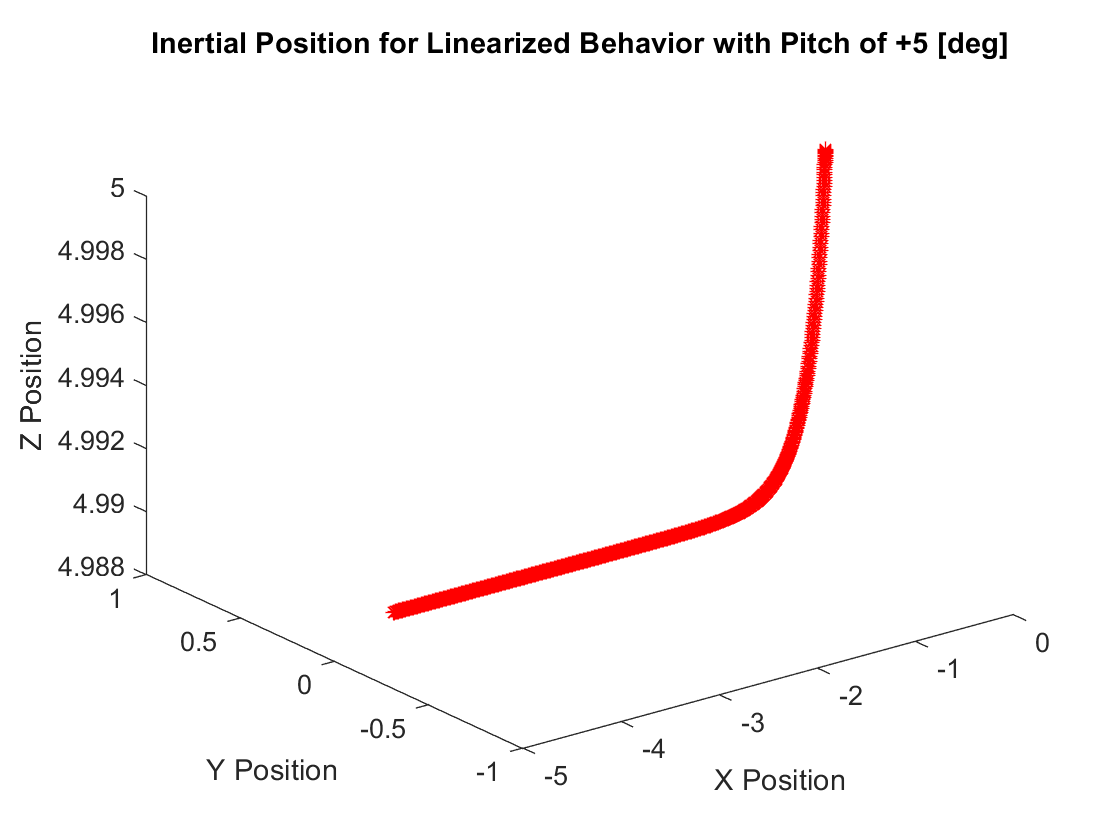

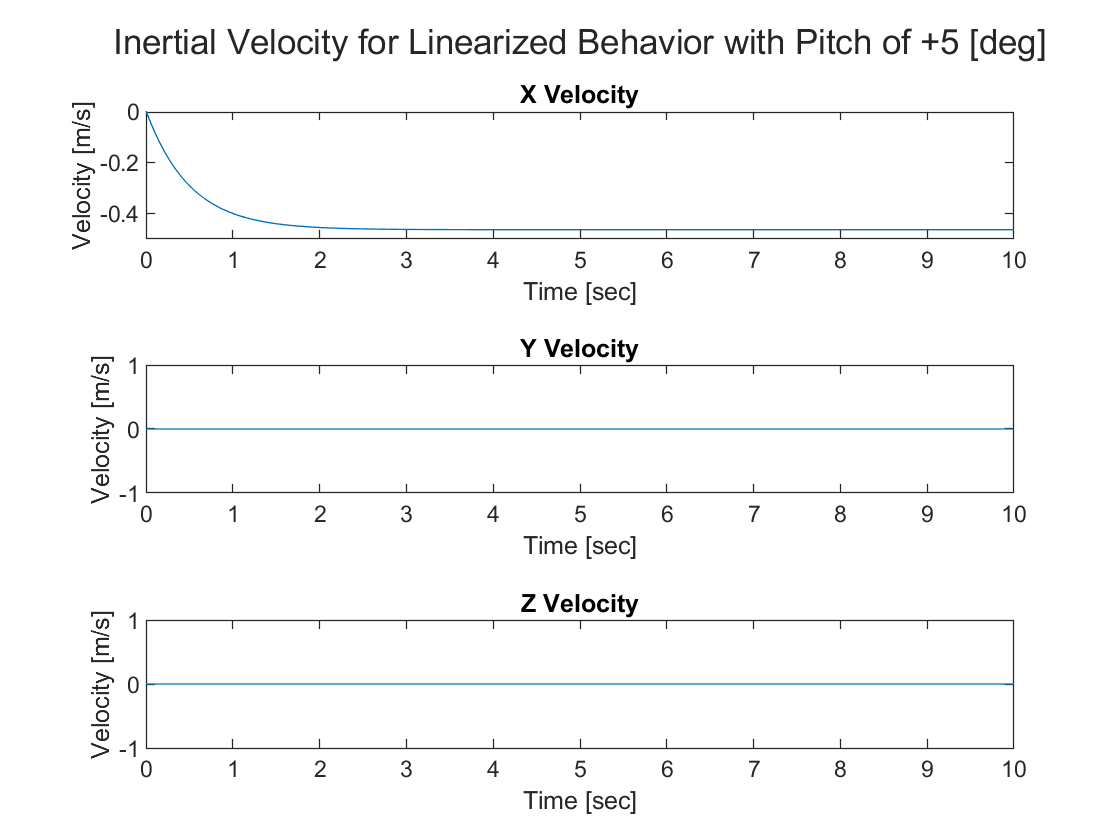

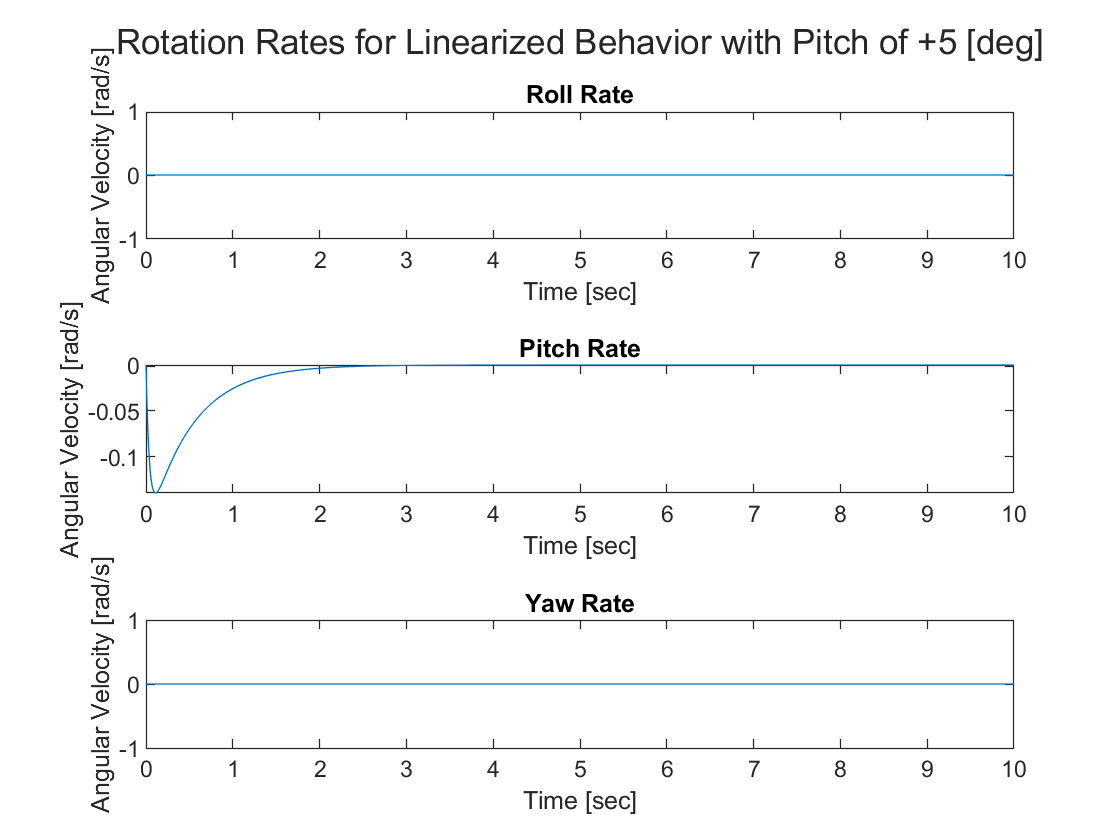

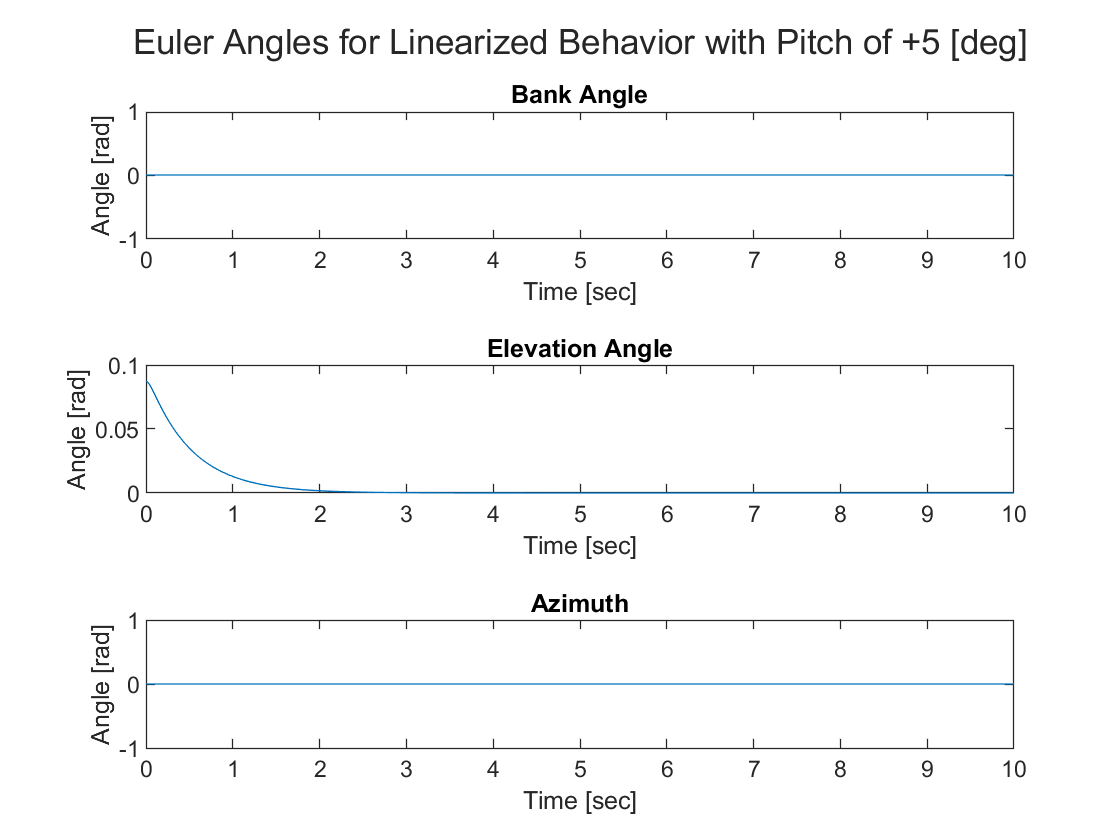

plutter(t,y,'Linearized Behavior with Pitch of +5 [deg]')

## Problem 2.c

### Initialize Variables

t = 0;
y = 0;
theta = 0;
p = 0.1;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationLin', tSpan, initialState);

### Plotting the results

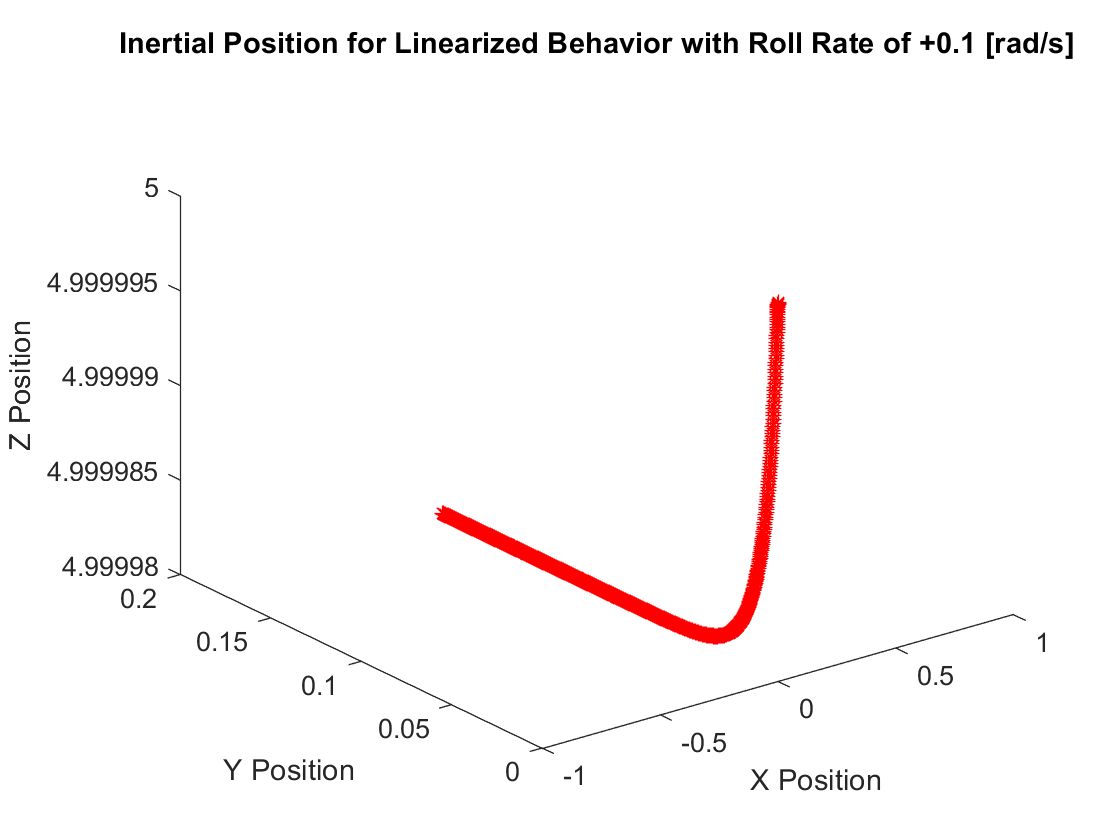

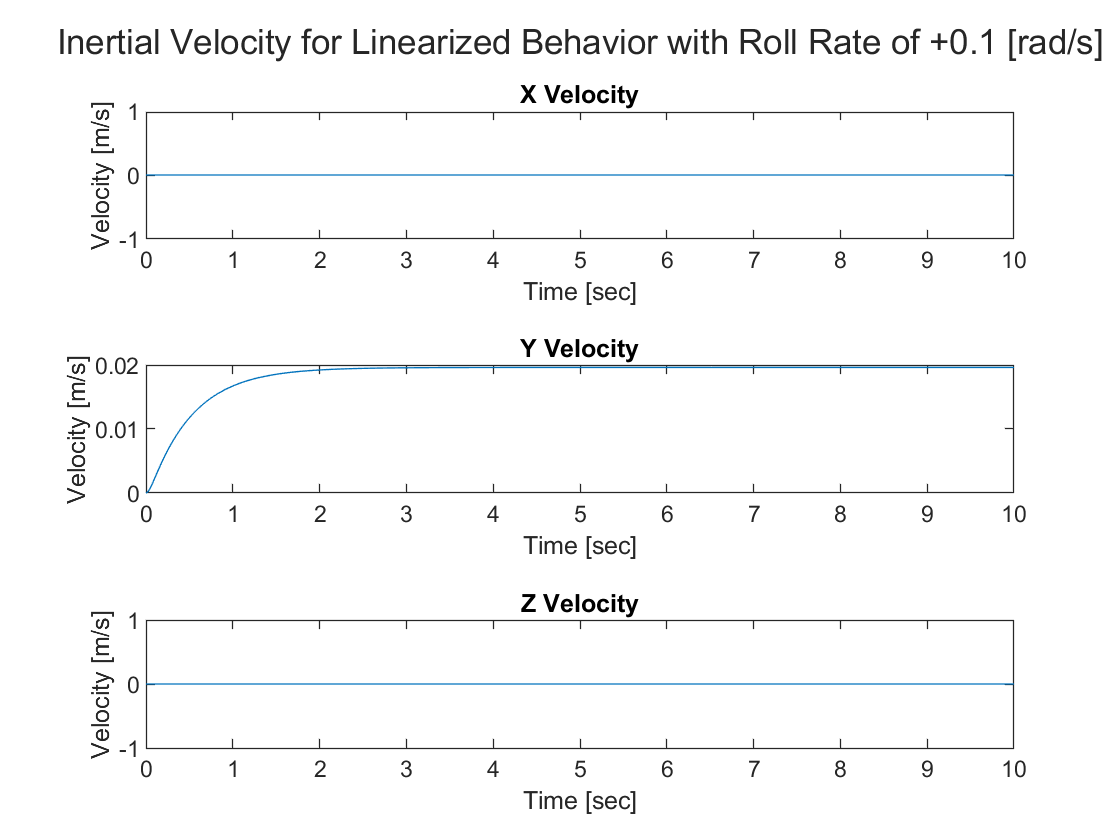

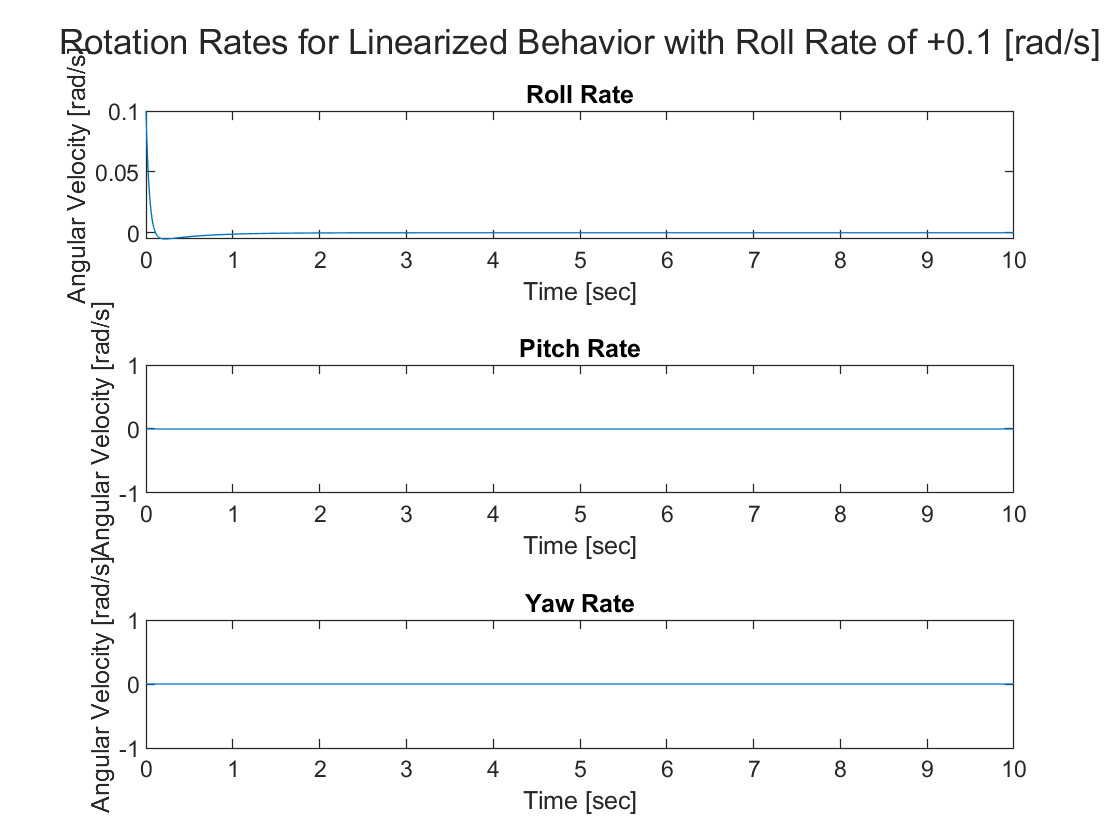

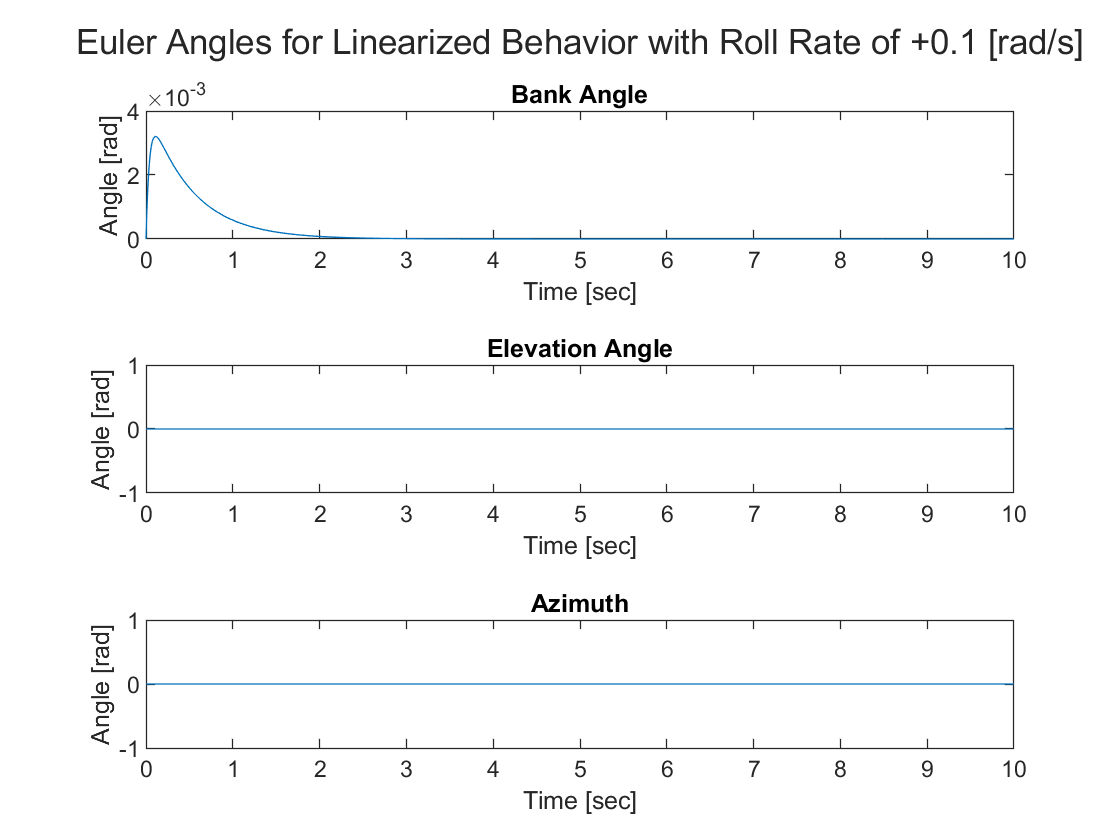

plutter(t,y,'Linearized Behavior with Roll Rate of +0.1 [rad/s]')

## Problem 2.d

### Initialize Variables

t = 0;
y = 0;
p = 0;
q = 0.1;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationLin', tSpan, initialState);

### Plotting the results

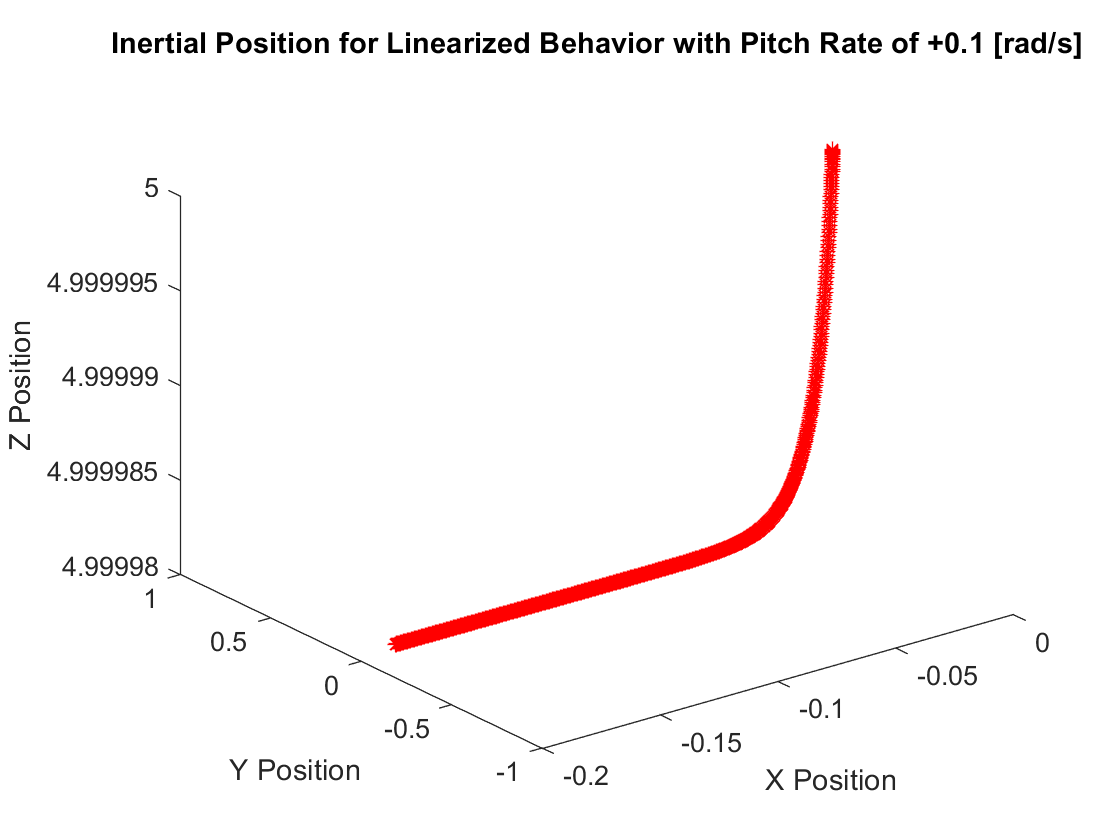

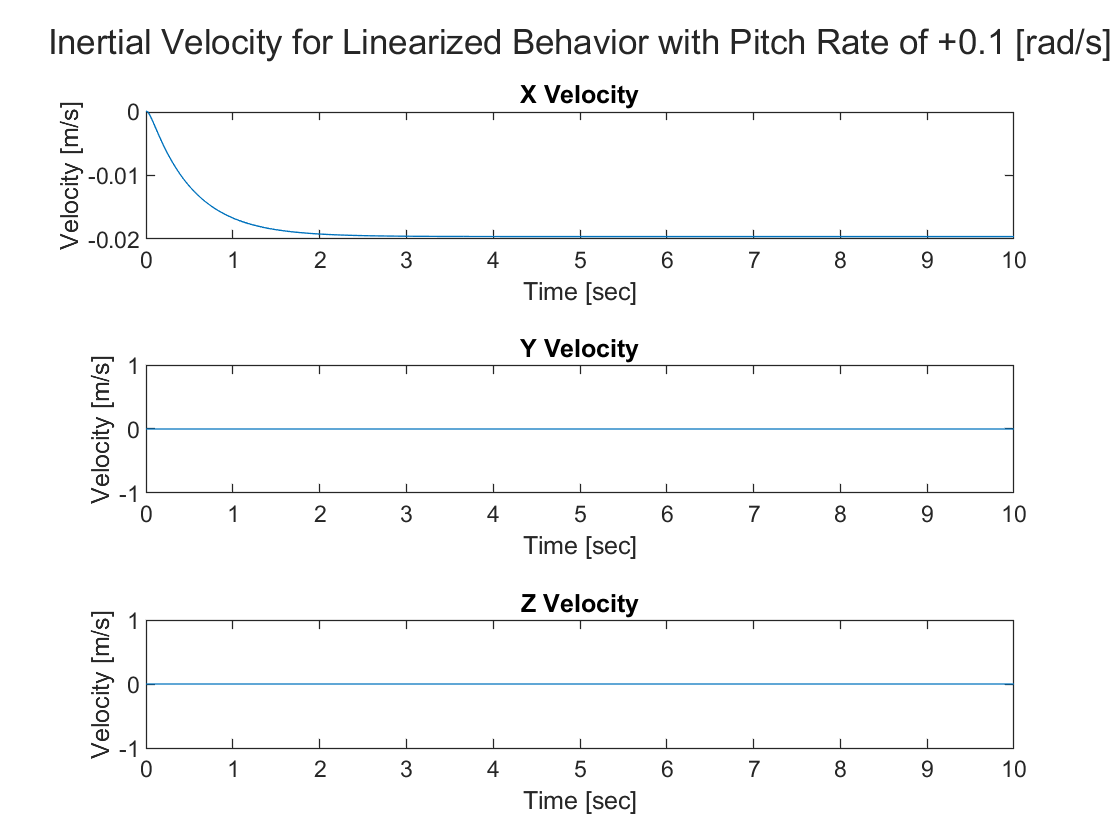

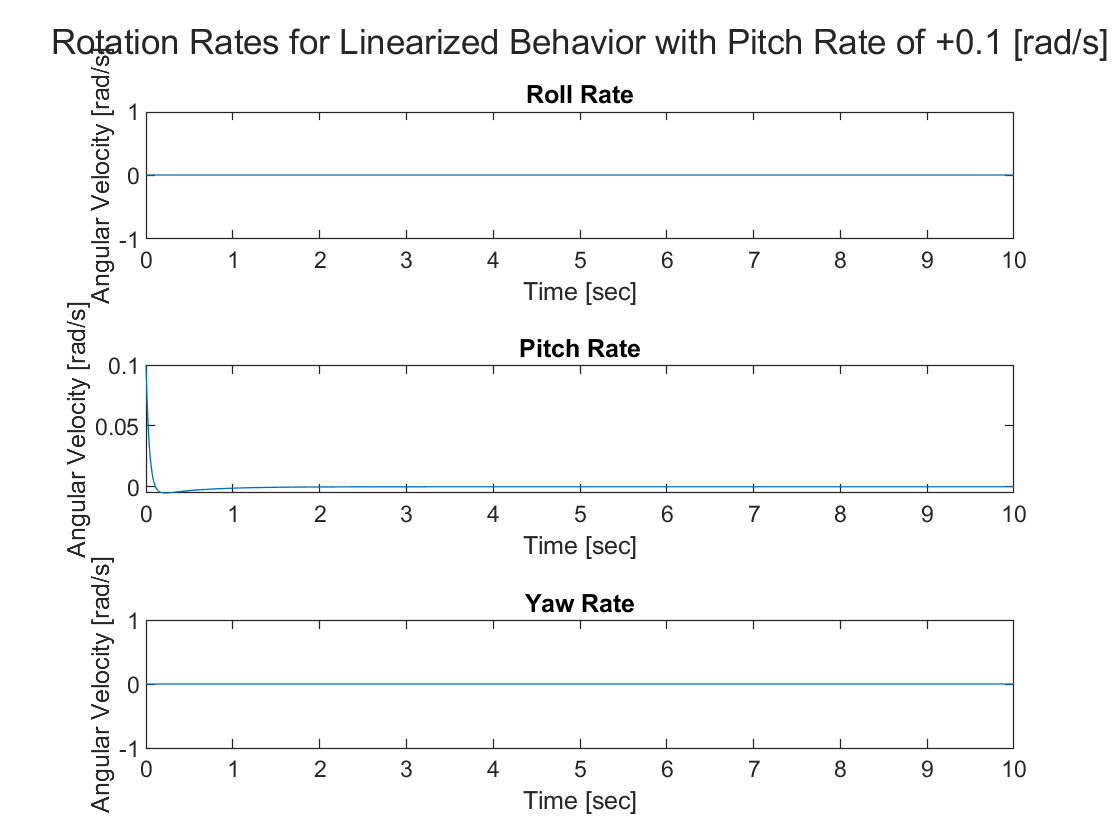

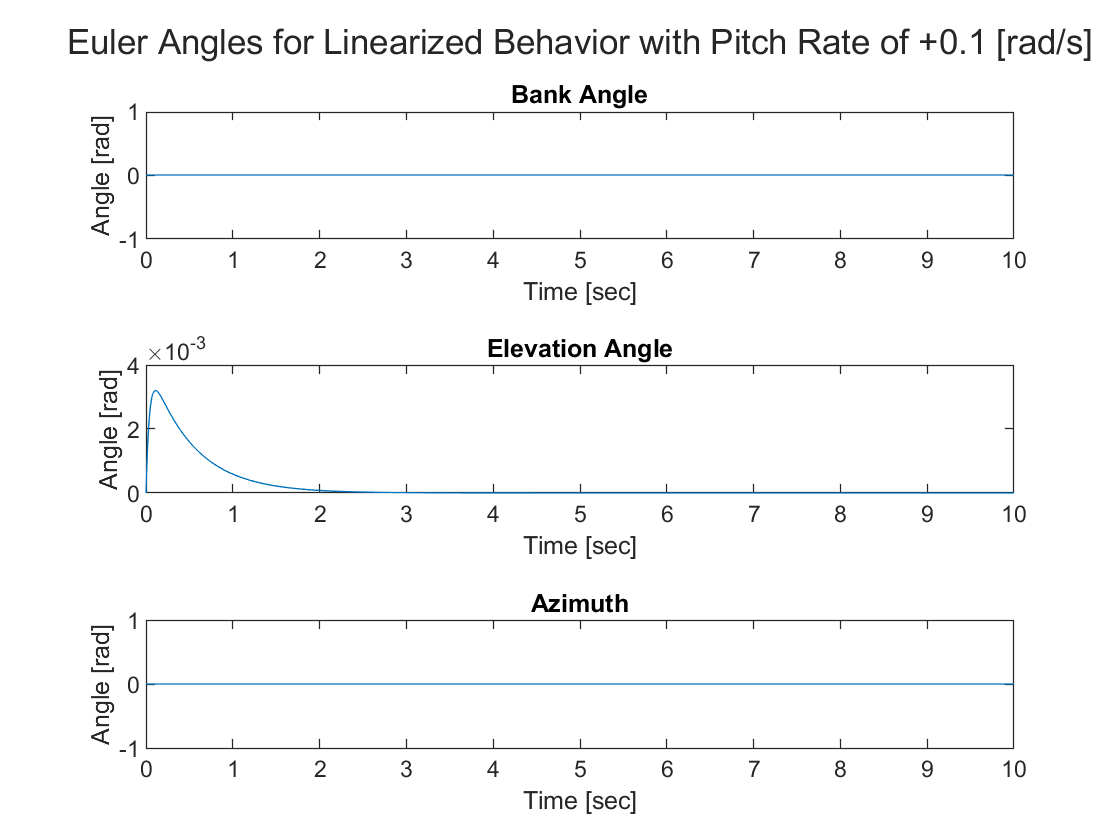

plutter(t,y,'Linearized Behavior with Pitch Rate of +0.1 [rad/s]')

## Problem 3

## Problem 3.a

### Initialize Variables

t = 0;
y = 0;
q = 0;
phi = deg2rad(5);

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationNonLinFC', tSpan, initialState);

### Plotting the results

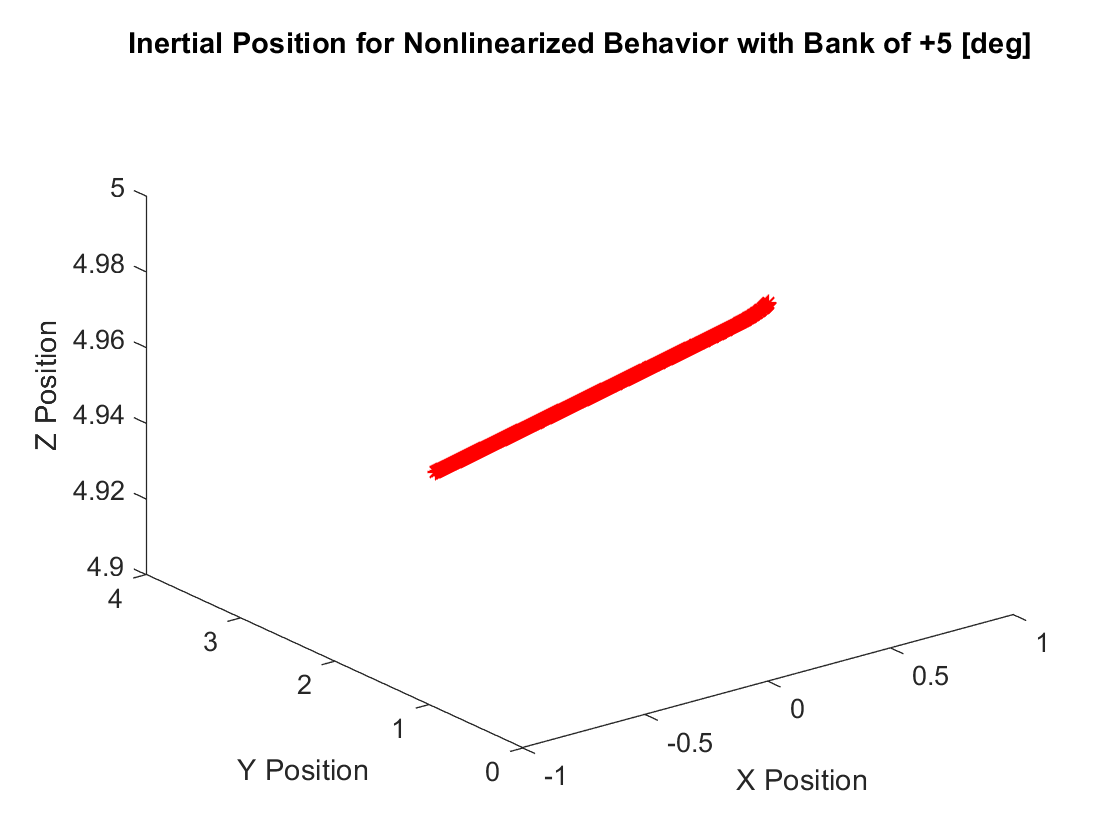

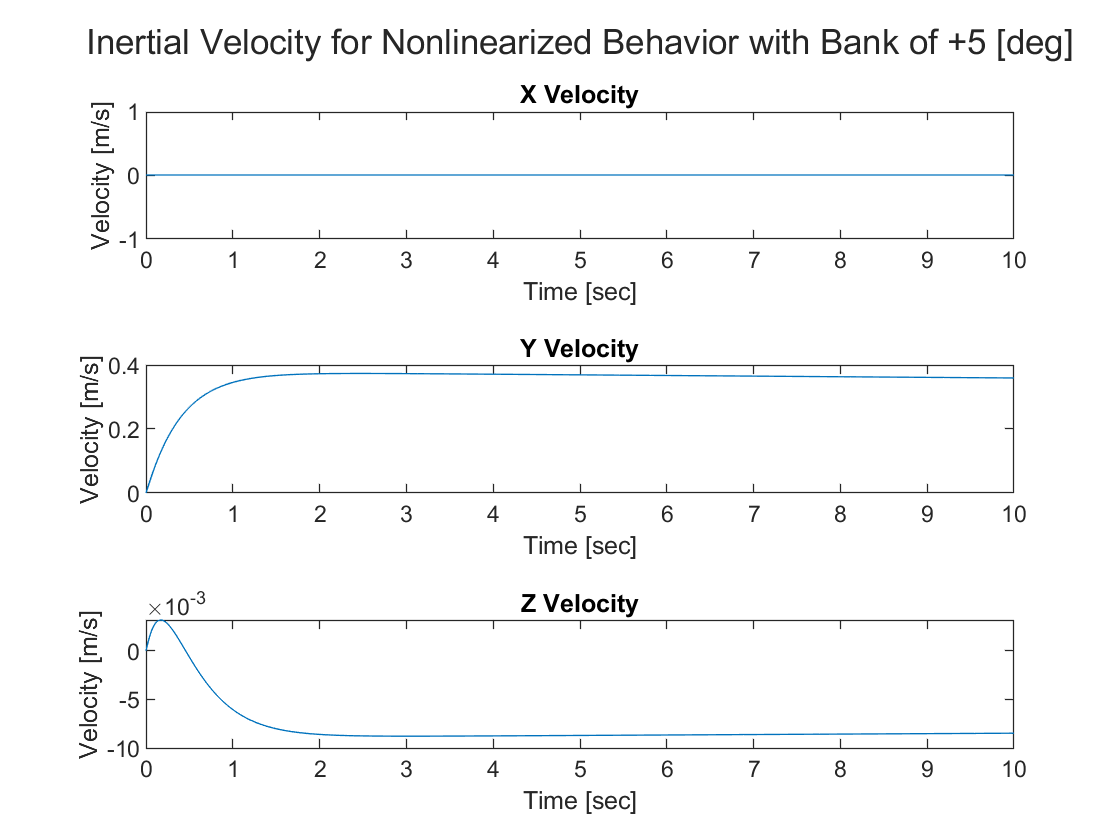

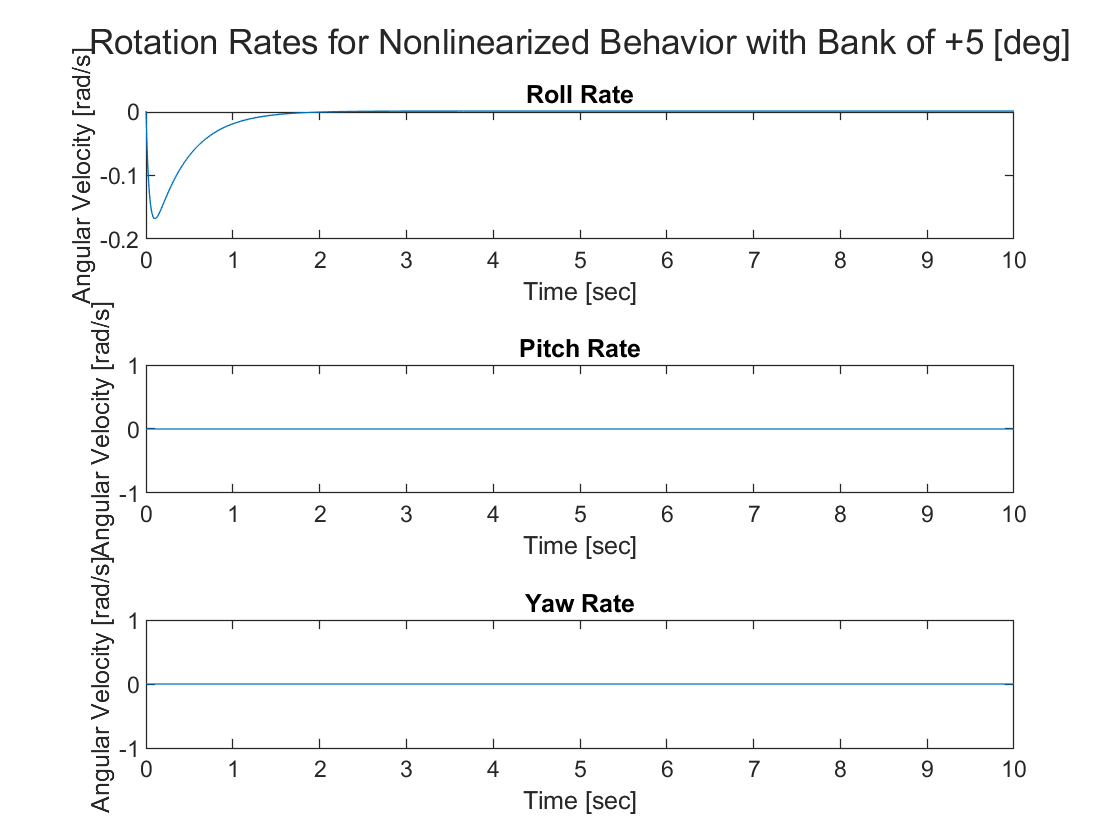

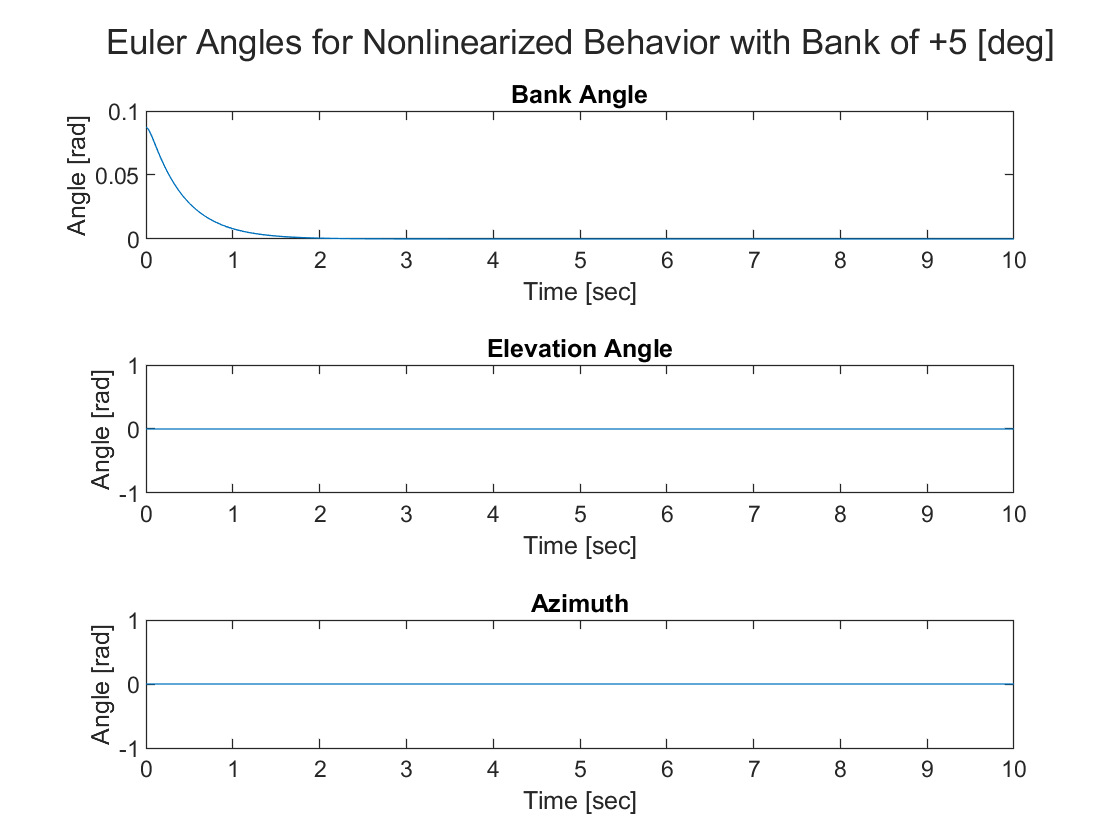

plutter(t,y,'Nonlinearized Behavior with Bank of +5 [deg]')

## Problem 3.b

### Initialize Variables

t = 0;
y = 0;
phi = 0;
theta = deg2rad(5);

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationNonLinFC', tSpan, initialState);

### Plotting the results

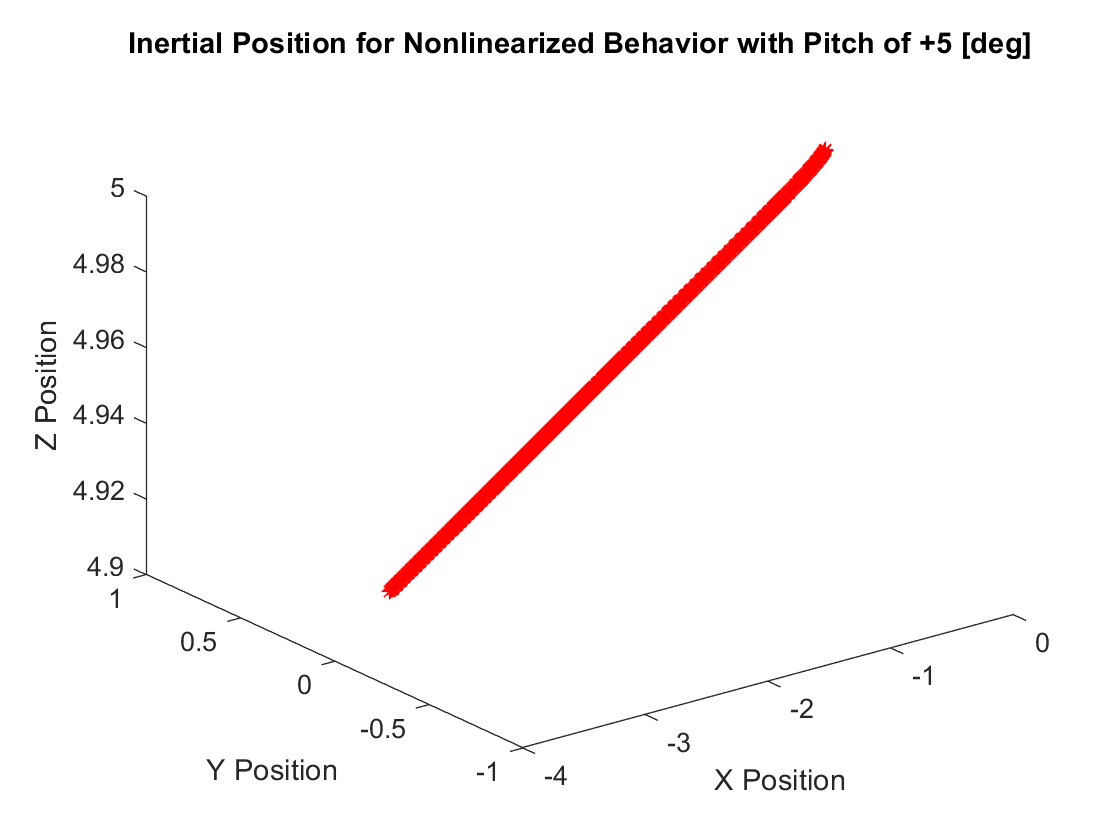

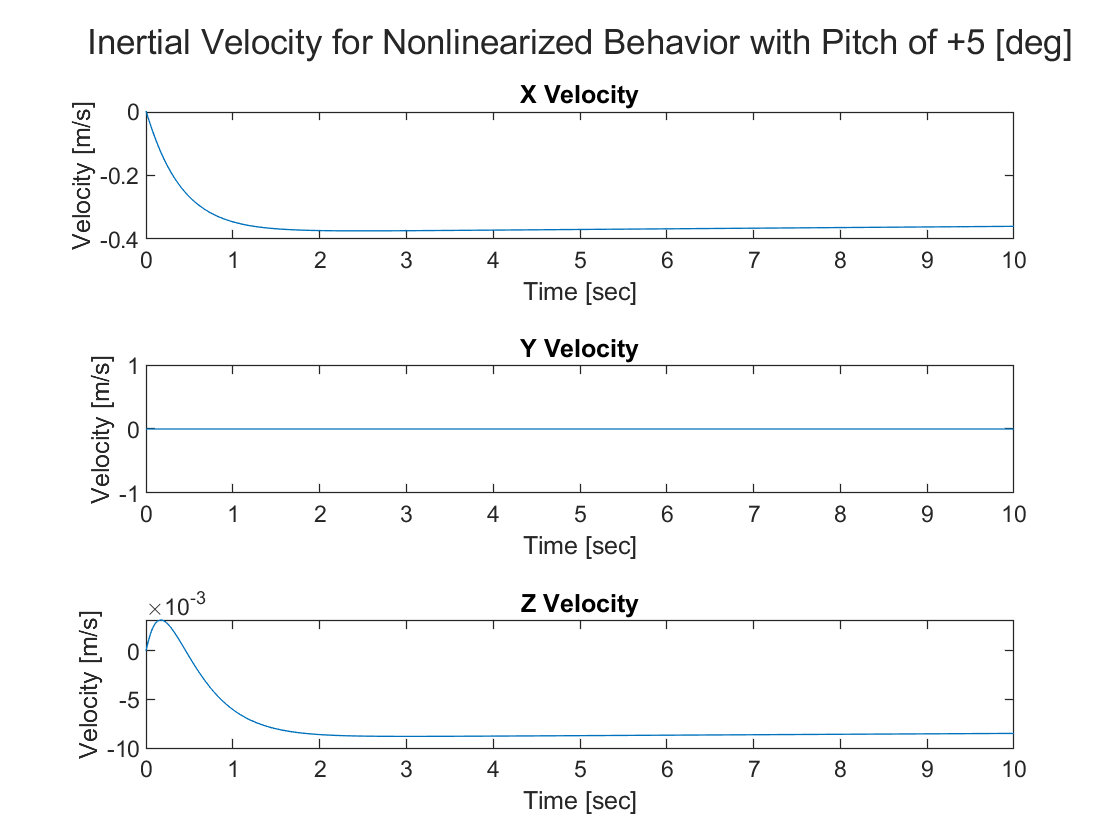

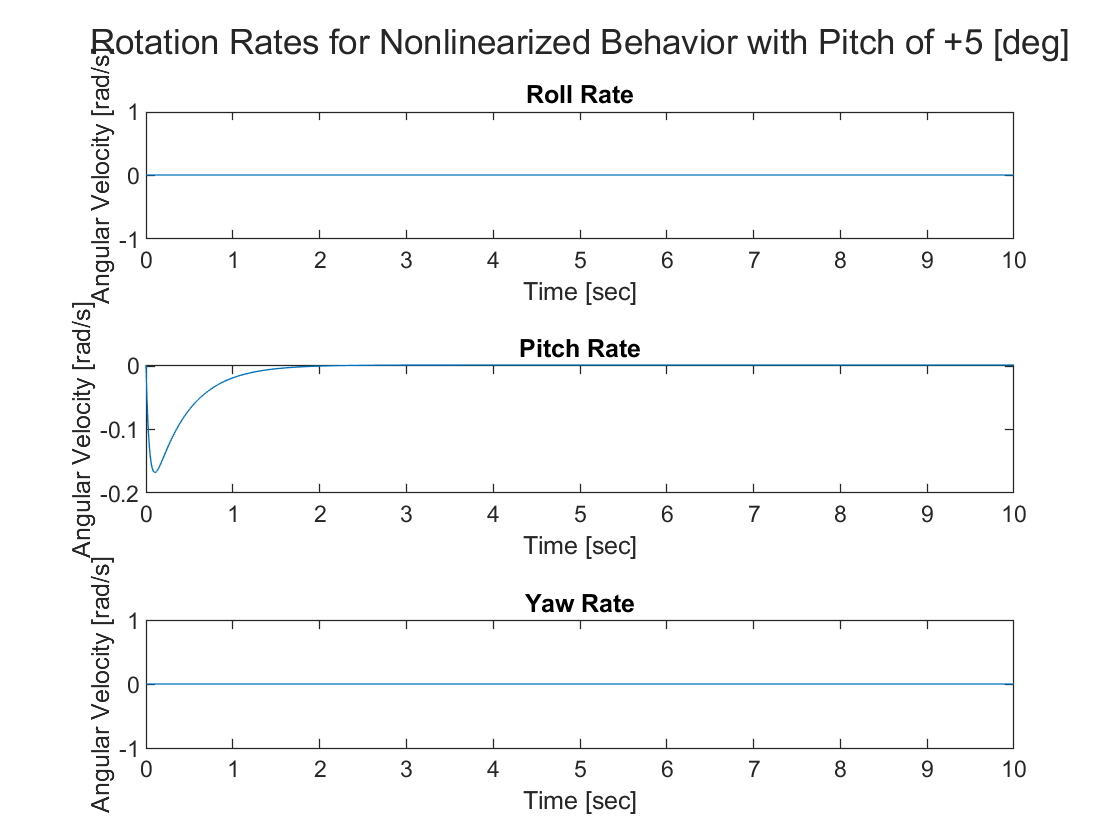

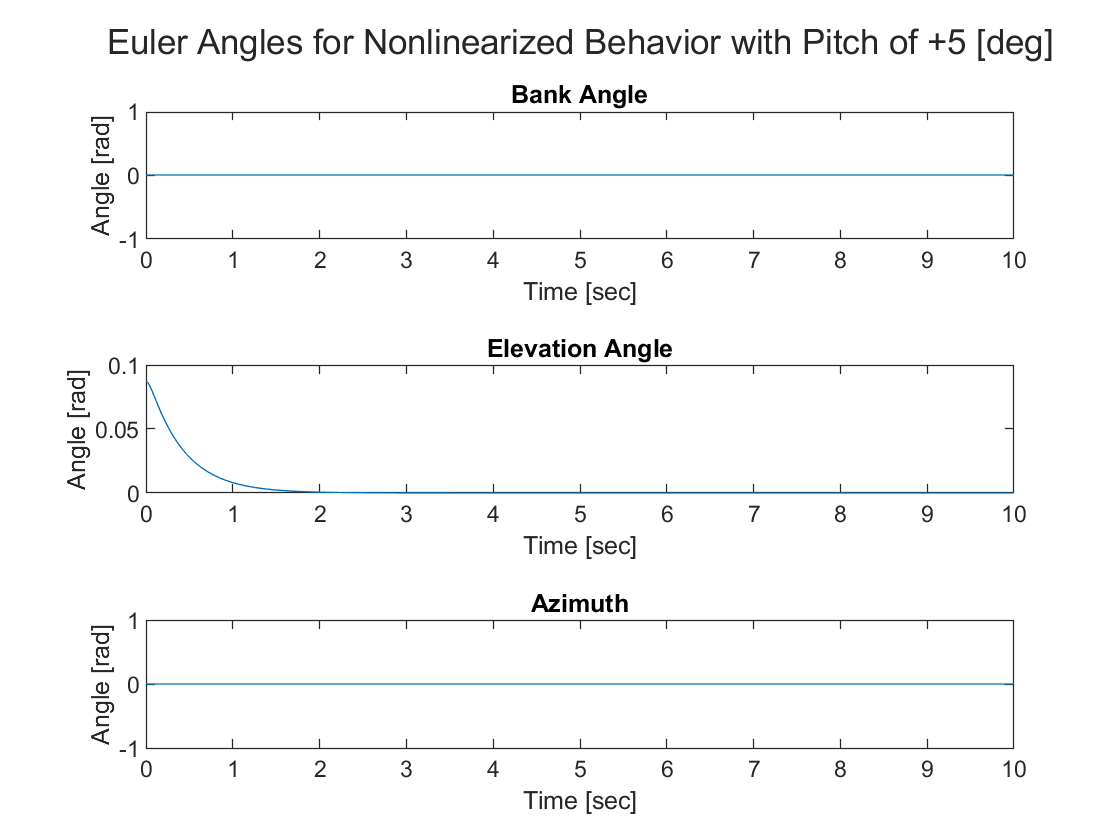

plutter(t,y,'Nonlinearized Behavior with Pitch of +5 [deg]')

## Problem 3.c

### Initialize Variables

t = 0;
y = 0;
theta = 0;
p = 0.1;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationNonLinFC', tSpan, initialState);

### Plotting the results

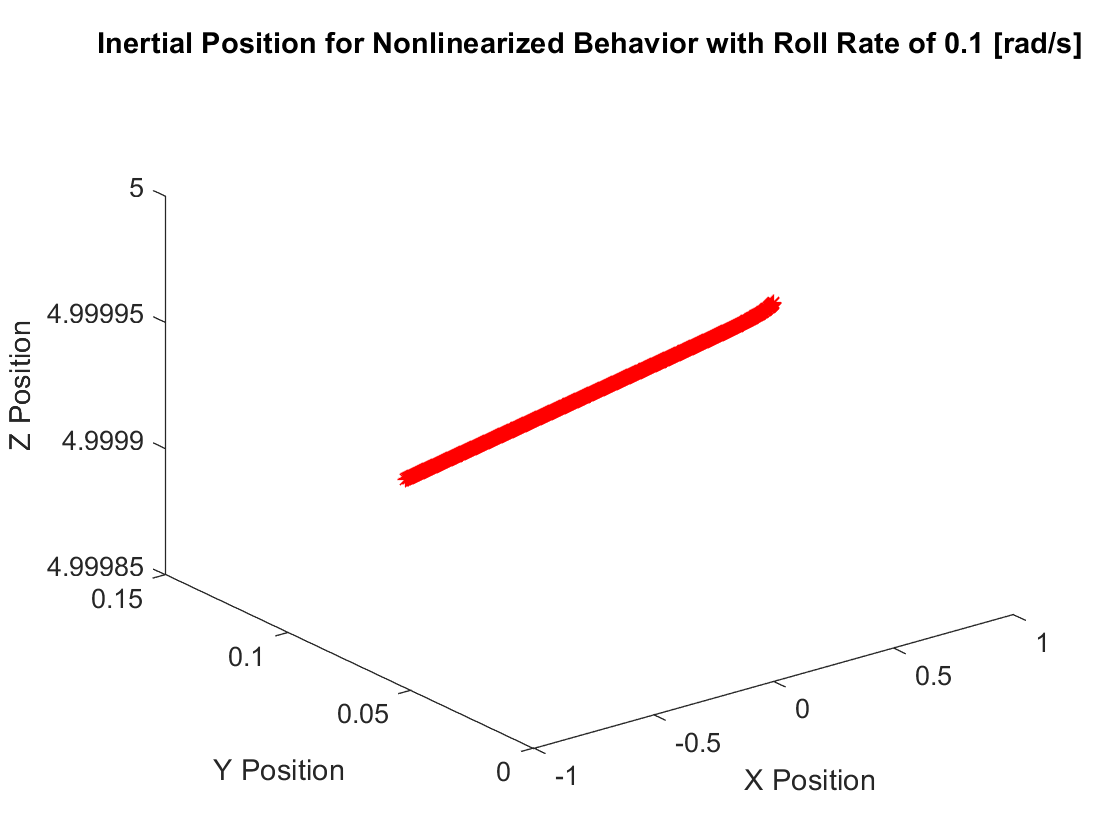

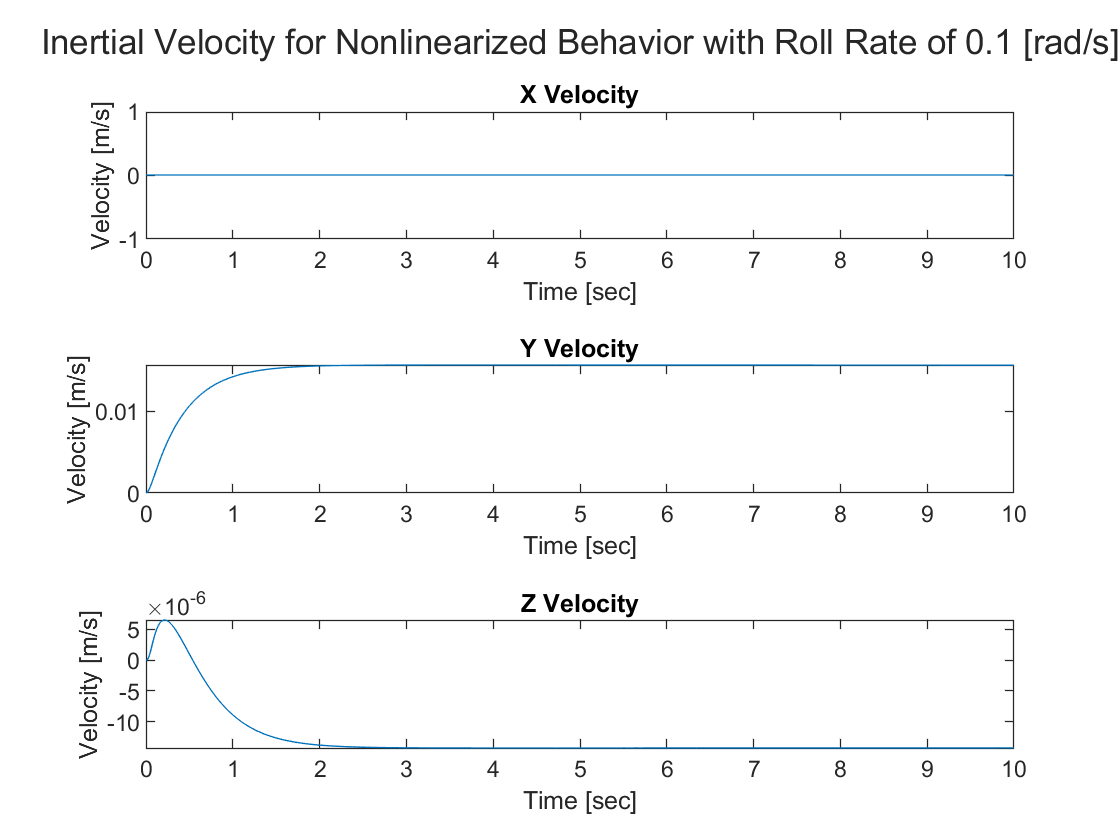

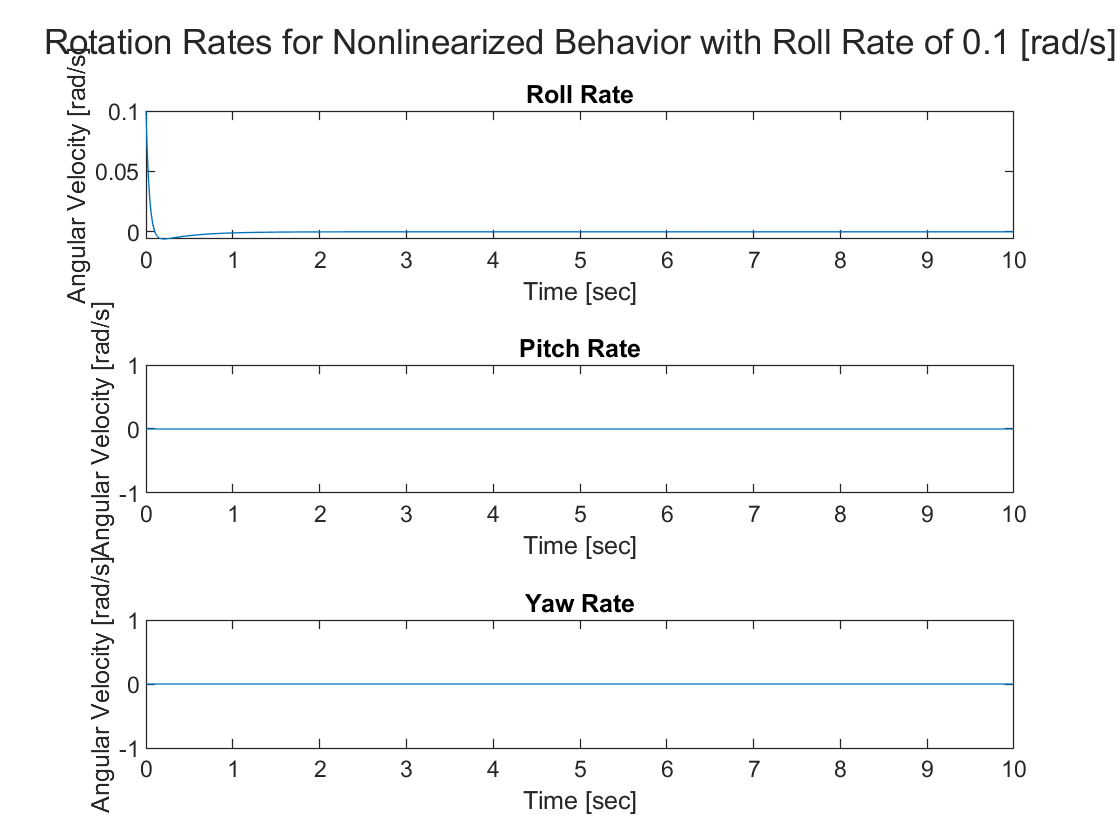

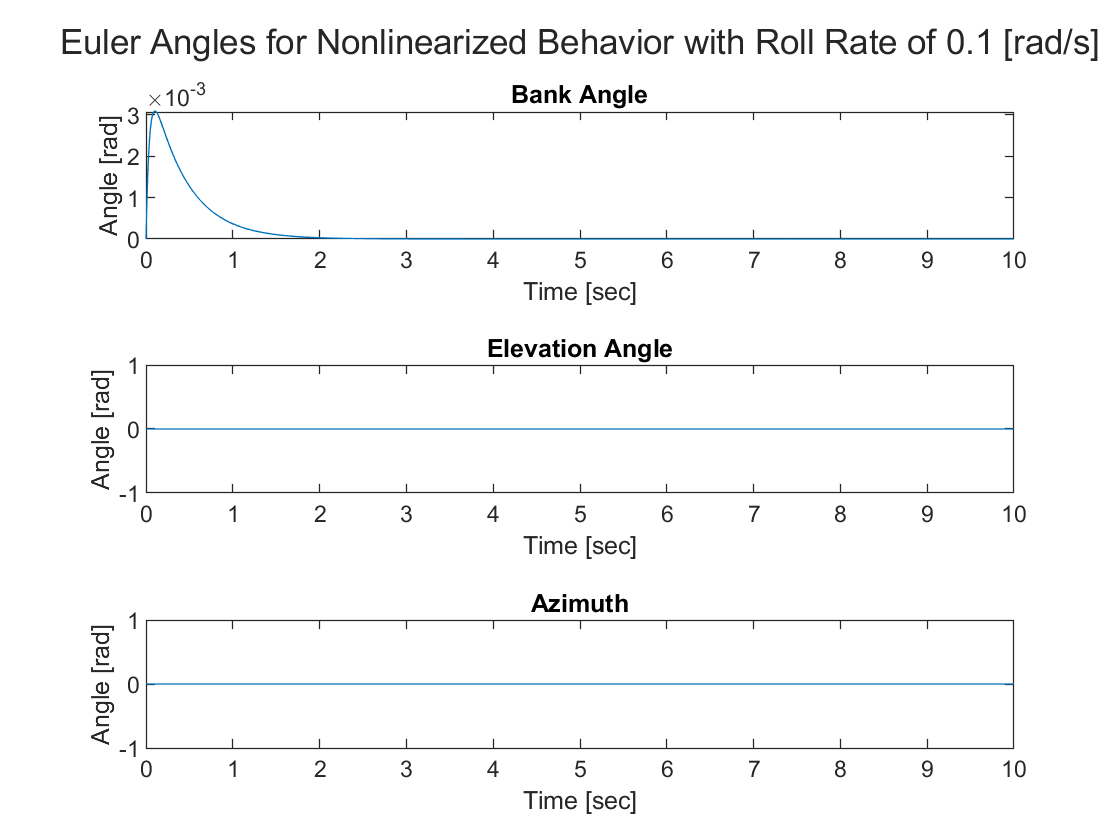

plutter(t,y,'Nonlinearized Behavior with Roll Rate of 0.1 [rad/s]')

## Problem 3.d

### Initialize Variables

t = 0;
y = 0;
p = 0;
q = 0.1;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationNonLinFC', tSpan, initialState);

### Plotting the results

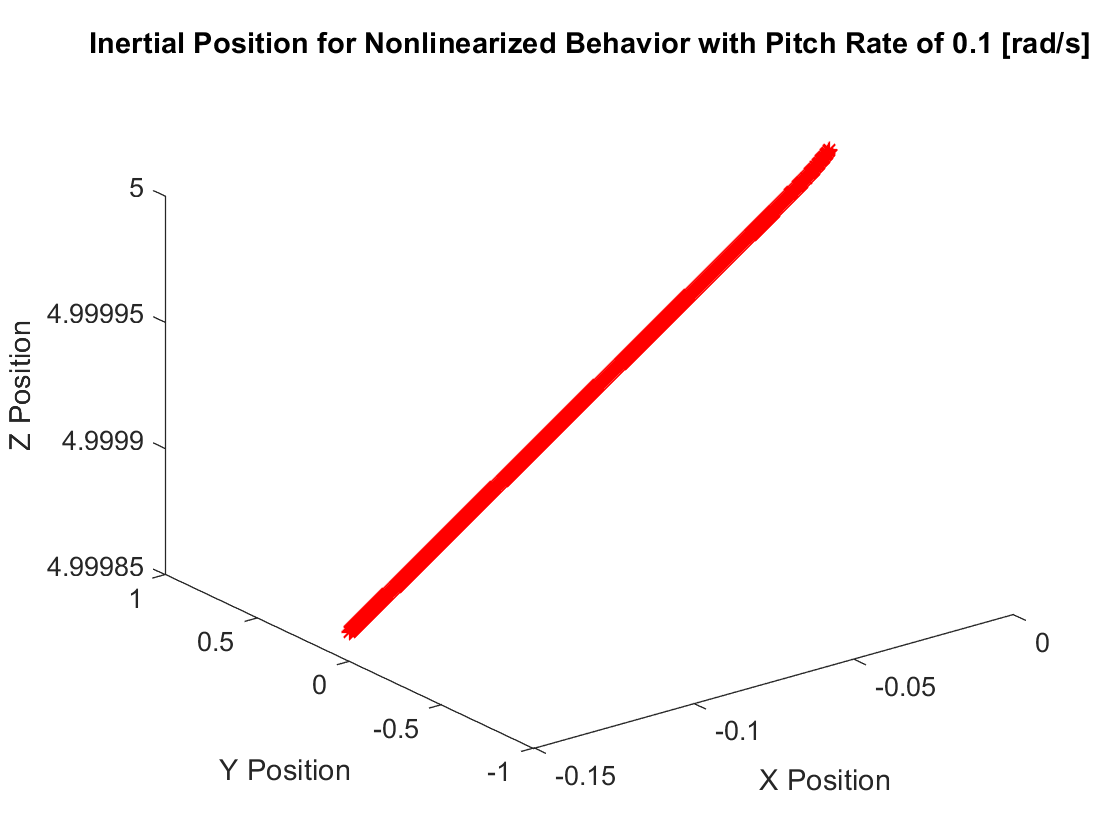

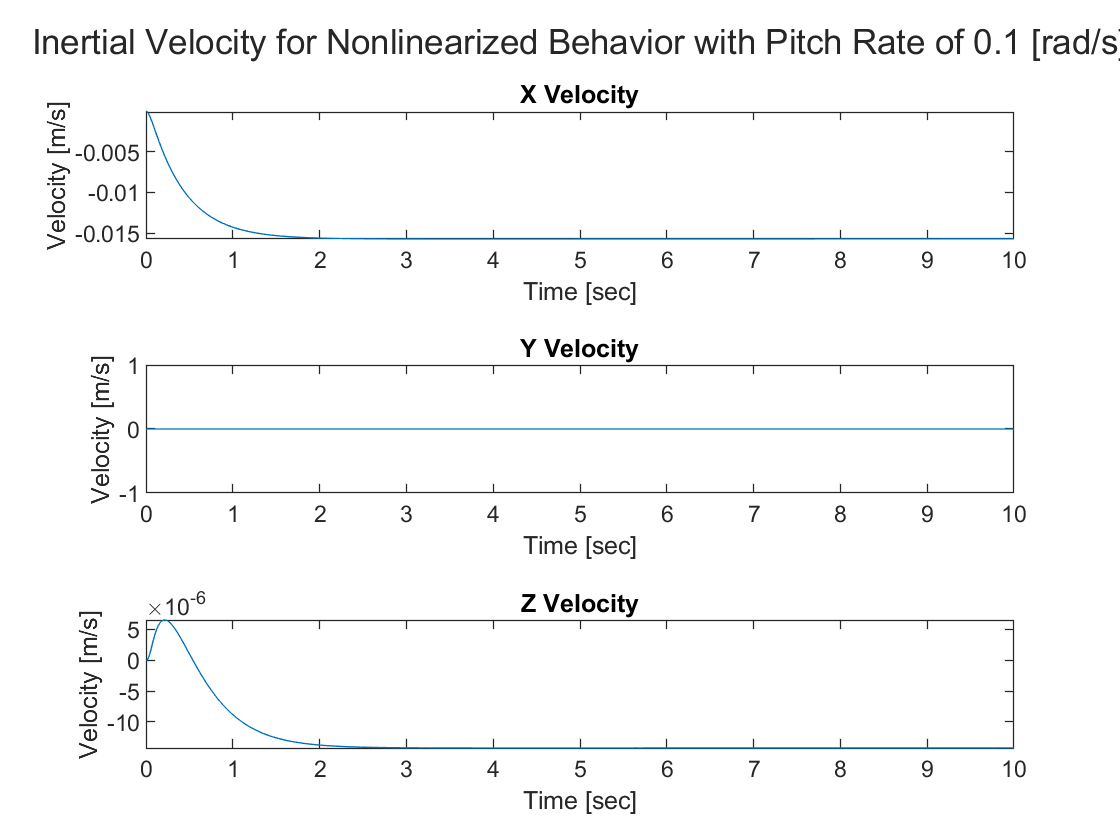

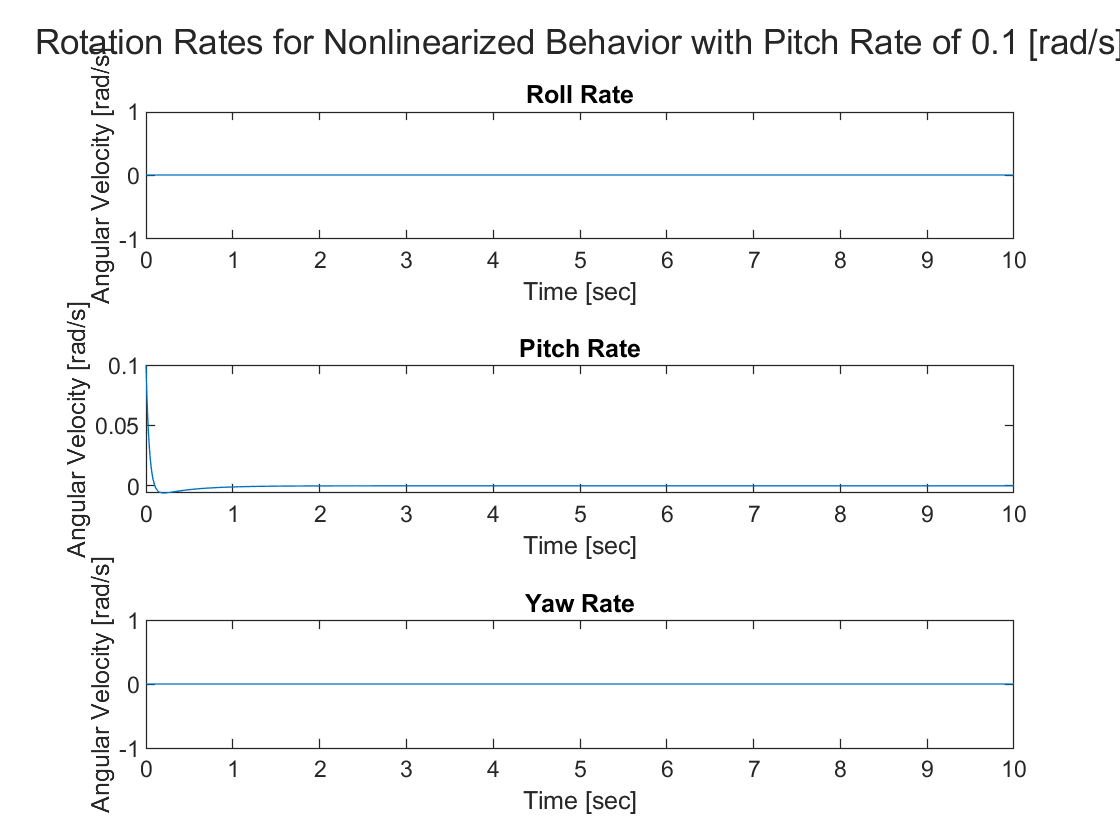

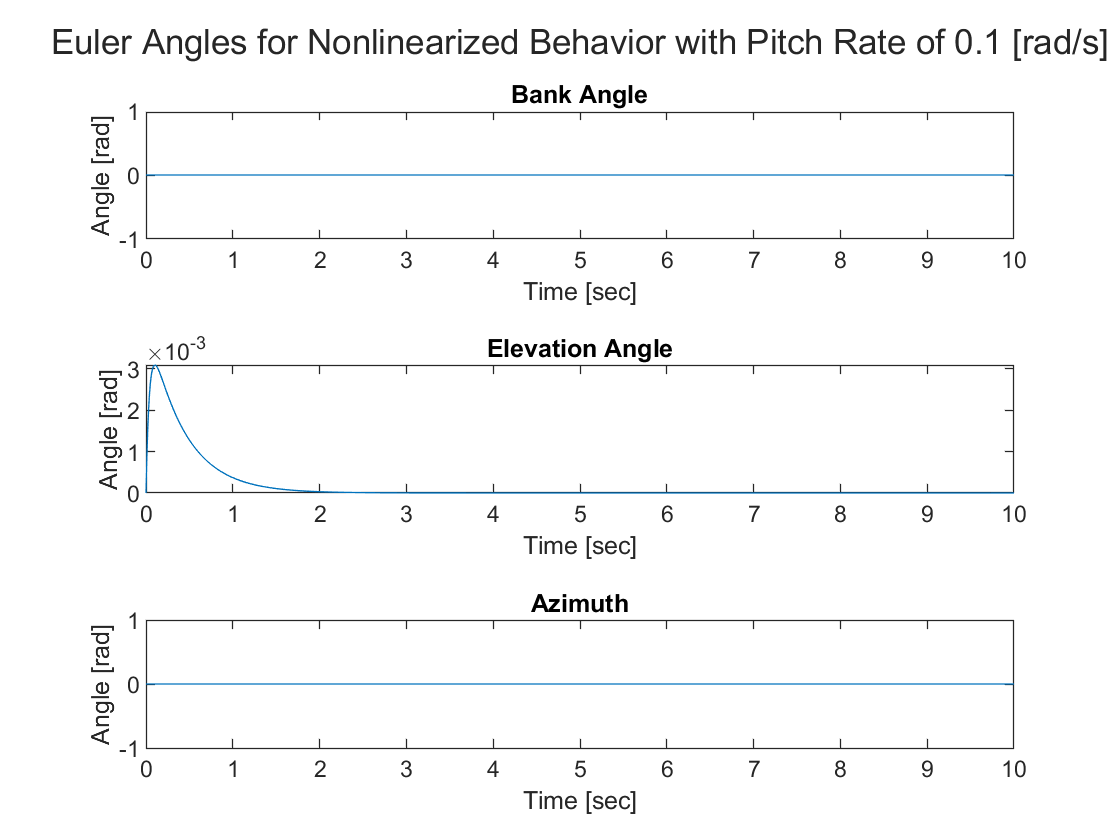

plutter(t,y,'Nonlinearized Behavior with Pitch Rate of 0.1 [rad/s]')

## Non- vs Linearized Discussion

The linearized model does not take into account the change in vertical velocity as a result of the rotation of the quadcopter.  Due to this, the change in vertical position is not similar to the nonlinearized model, which continuously descends because a control law to neutralize the vertical velocity has not been implemented yet.  Additionally, both models develop some sort of translational velocity as a result of the initial deviations, again because a control law to neutralize the velocity has not yet been implemented.  Because of both of these actions, neither the linearized nor the nonlinearized models that utilize feedback control on the angular rates and euler angles can be classified as a steady hover state.

## Problem 4

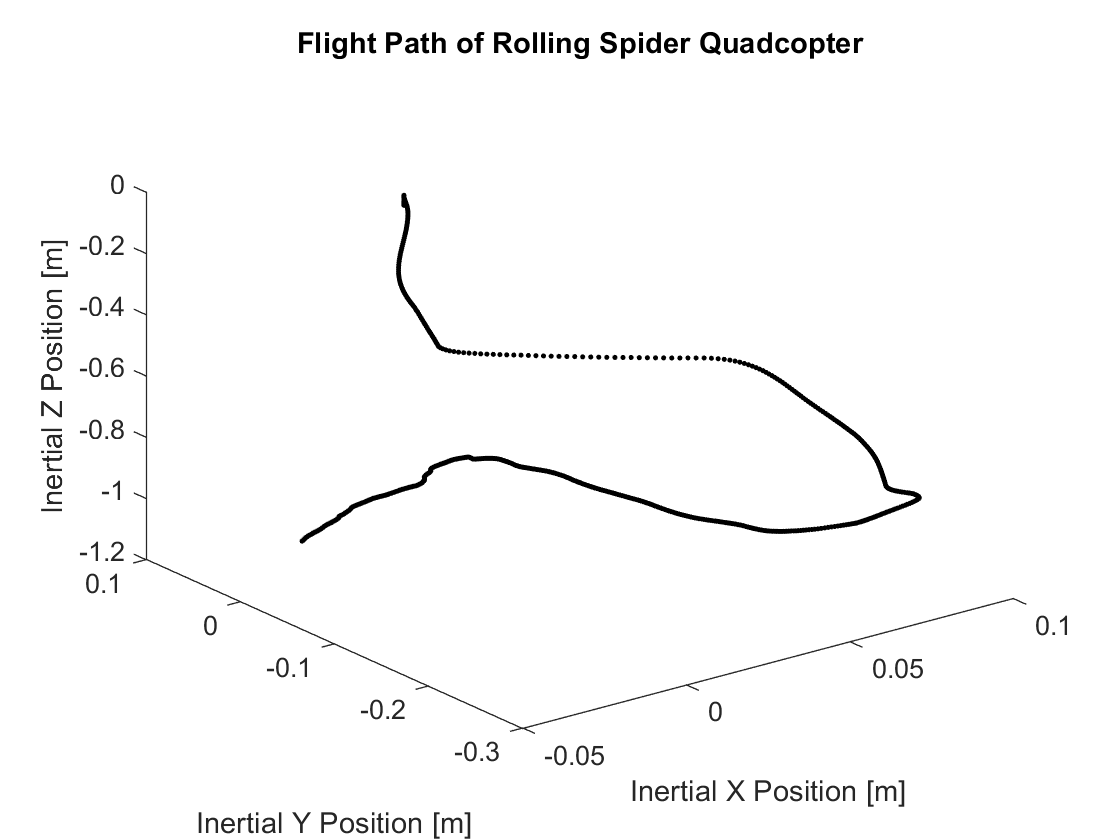

load('RSdata_one_1420.mat');
time=rt_estimatedStates.time(1:1200);
x=rt_estimatedStates.signals.values(1:1200,1);
y=rt_estimatedStates.signals.values(1:1200,2);
z=rt_estimatedStates.signals.values(1:1200,3);
yaw=rt_estimatedStates.signals.values(1:1200,4);
pitch=rt_estimatedStates.signals.values(1:1200,5);
roll=rt_estimatedStates.signals.values(1:1200,6);
Vx=rt_estimatedStates.signals.values(1:1200,7);
Vy=rt_estimatedStates.signals.values(1:1200,8);
Vz=rt_estimatedStates.signals.values(1:1200,9);
p=rt_estimatedStates.signals.values(1:1200,10);
q=rt_estimatedStates.signals.values(1:1200,11);
r=rt_estimatedStates.signals.values(1:1200,12);

figure()
plot3(x,y,z,'.k')
title('Flight Path of Rolling Spider Quadcopter')
xlabel('Inertial X Position [m]')
ylabel('Inertial Y Position [m]')
zlabel('Inertial Z Position [m]')

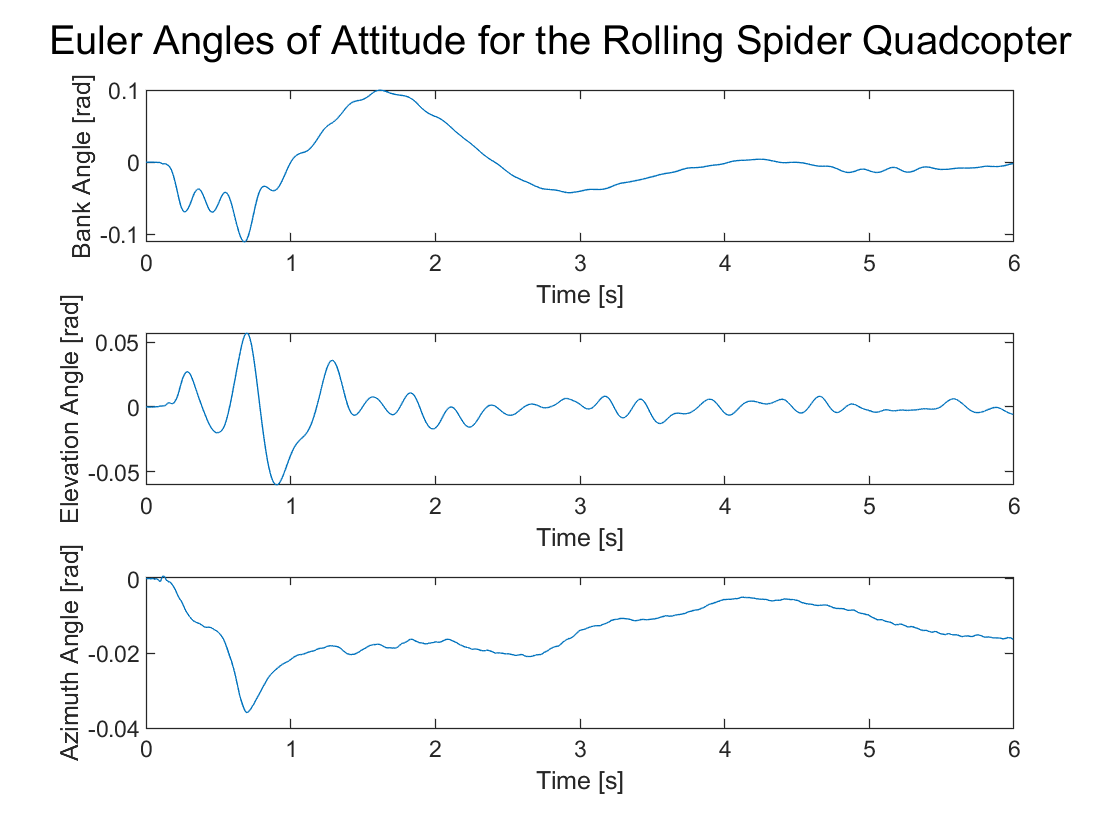


figure()
subplot(3,1,1)
plot(time,roll)
xlabel('Time [s]')
ylabel('Bank Angle [rad]')

subplot(3,1,2)
plot(time,pitch)
xlabel('Time [s]')
ylabel('Elevation Angle [rad]')

subplot(3,1,3)
plot(time,yaw)
xlabel('Time [s]')
ylabel('Azimuth Angle [rad]')

sgtitle('Euler Angles of Attitude for the Rolling Spider Quadcopter')

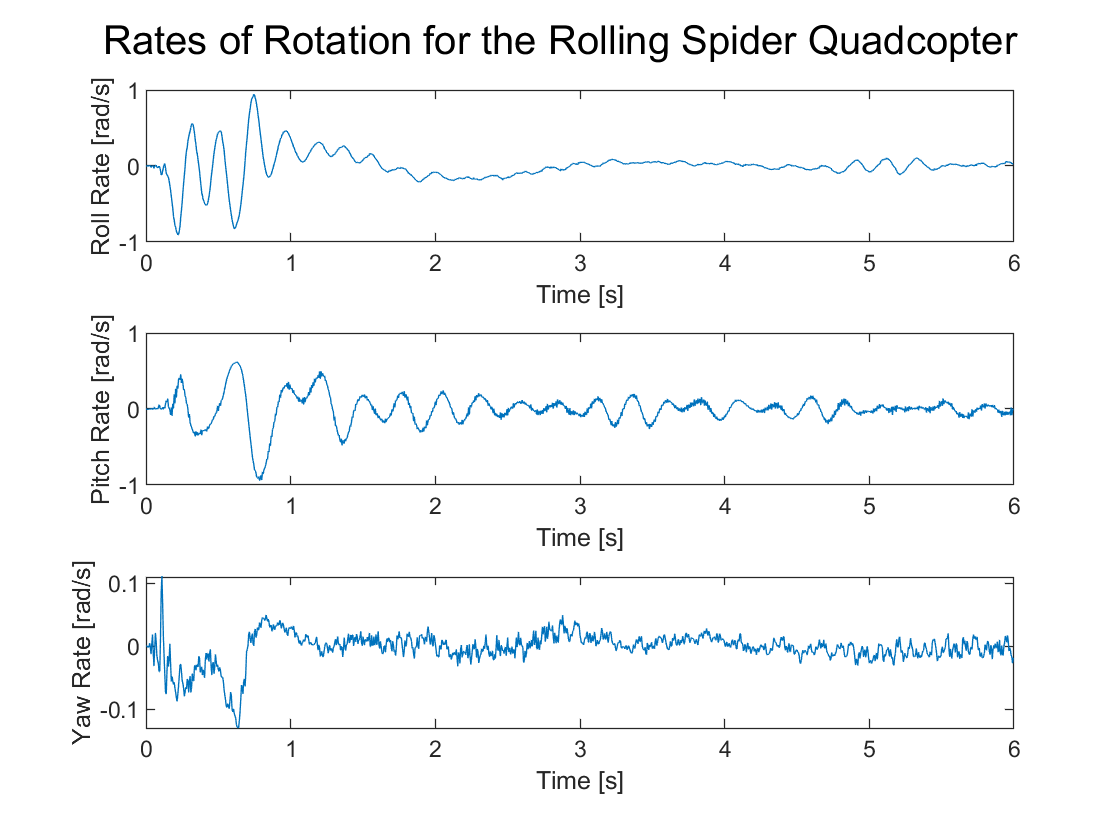


figure()
subplot(3,1,1)
plot(time,p)
xlabel('Time [s]')
ylabel('Roll Rate [rad/s]')

subplot(3,1,2)
plot(time,q)
xlabel('Time [s]')
ylabel('Pitch Rate [rad/s]')

subplot(3,1,3)
plot(time,r)
xlabel('Time [s]')
ylabel('Yaw Rate [rad/s]')

sgtitle('Rates of Rotation for the Rolling Spider Quadcopter')

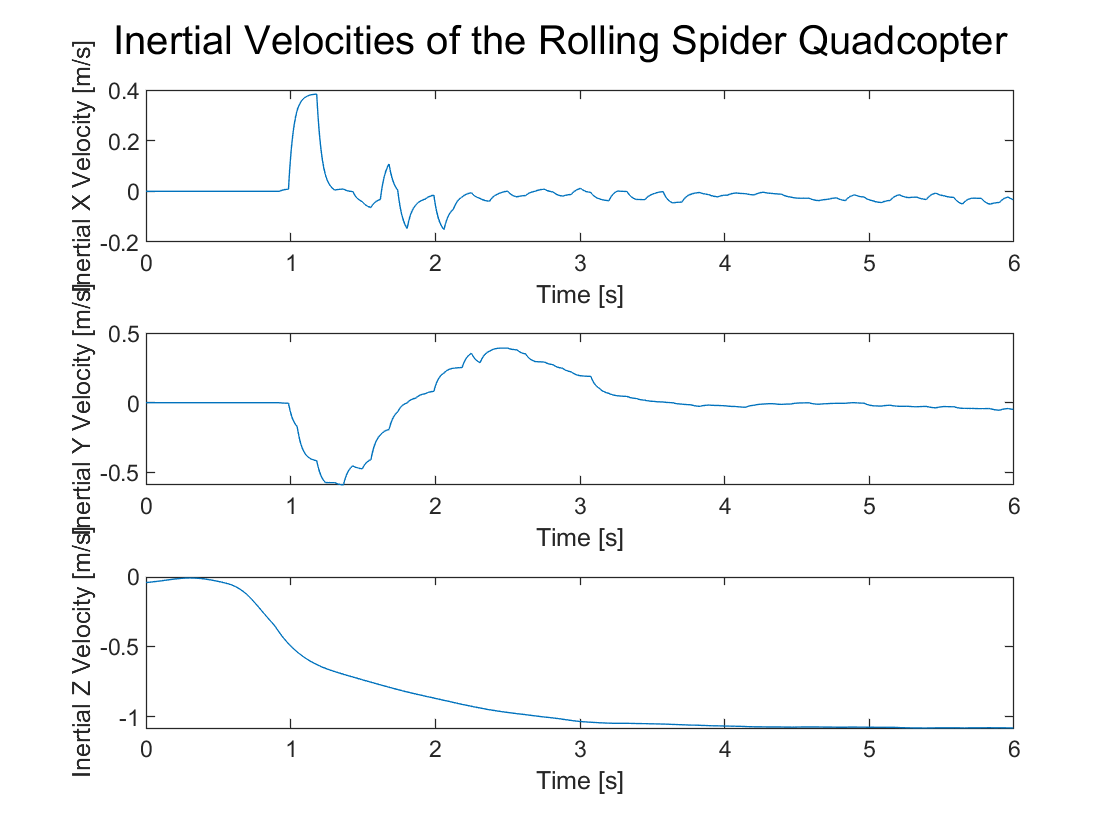


figure()
subplot(3,1,1)
plot(time,Vx)
xlabel('Time [s]')
ylabel('Inertial X Velocity [m/s]')

subplot(3,1,2)
plot(time,Vy)
xlabel('Time [s]')
ylabel('Inertial Y Velocity [m/s]')

subplot(3,1,3)
plot(time,z)
xlabel('Time [s]')
ylabel('Inertial Z Velocity [m/s]')

sgtitle('Inertial Velocities of the Rolling Spider Quadcopter')

## Rolling Spider Discussion

We see that the quadcopter follows the non-linear model in that it develops a decent rate of ~1 m/s that is constant for the rest of the time the copter is flying. Additionally it develops a translational velocity in the X direction at a speed of -0.5 m/s that also remains constant for the flight. This means that the copter does not apply control to cancel out its velocity (because the control law we used did not take any feedback from velocity). Unlike the models, the copter’s rotation rates oscillate and never fully equilibrate to zero. They oscillate around a final amplitude of +/- 0.25 rad/s. This makes sense because the control law only uses a proportional and derivative gain and not an integral gain to equilibrate the rates to zero. As is evident from the position graph, the copter does not reach a steady hover state. This agrees with both the linearized and non-linearized models.The Euler attitude angles of the copter return to zero just as in both linearized and non-linearized models since there is a control law on the angle.